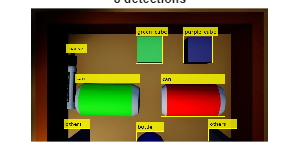

  others          0.91
  bottle          0.93
  others          0.91
  green_cube      0.94
  purple_cube     0.95
  marker          0.90
  can             0.94
  can             0.95


% ============= DIRECT INFERENCE WITHOUT WRAPPER =============
onnxPath = 'C:\Users\ataul\Desktop\RoboCup\RoboCup_ARM_1\RoboCup_ARM\modelData\best.onnx';

classNames = {'blue_cube', 'bottle', 'can', 'green_cube', ...
              'marker', 'others', 'purple_cube', 'red_cube', ...
              'spam', 'weight'};

% Import network
net = importNetworkFromONNX(onnxPath);

% ---- Predict function ----
function [bboxes, scores, labels] = predictYOLOv8(net, img, classNames, threshold)
    if nargin < 4; threshold = 0.3; end
    
    origH = size(img,1);
    origW = size(img,2);
    inputSize = 640;
    
    % Letterbox resize to 640x640
    scale   = min(inputSize/origH, inputSize/origW);
    newH    = round(origH * scale);
    newW    = round(origW * scale);
    padTop  = floor((inputSize - newH) / 2);
    padLeft = floor((inputSize - newW) / 2);
    
    resized = imresize(img, [newH newW]);
    canvas  = uint8(128 * ones(inputSize, inputSize, 3));
    canvas(padTop+1:padTop+newH, padLeft+1:padLeft+newW, :) = resized;
    
    % Normalize to [0,1] and format for network
    imgNorm = single(canvas) / 255.0;
    imgDL   = dlarray(permute(imgNorm, [1 2 3]), 'SSC');  % H W C
    imgDL   = reshape(imgDL, [inputSize inputSize 3 1]);   % H W C N
    
    % Run inference
    output = predict(net, imgDL);
    
    % Parse YOLOv8 output: [batch, 4+numClasses, num_anchors]
    outData = extractdata(output);
    outData = squeeze(outData);  % [4+numClasses, num_anchors]
    
    numClasses  = length(classNames);
    numAnchors  = size(outData, 2);
    
    % Split boxes and class scores
    boxPreds    = outData(1:4, :);        % [cx cy w h]
    classPreds  = outData(5:end, :);      % [numClasses x numAnchors]
    
    % Get best class score per anchor
    [maxScores, classIdx] = max(classPreds, [], 1);
    
    % Filter by threshold
    keepIdx = maxScores >= threshold;
    if ~any(keepIdx)
        bboxes = []; scores = []; labels = [];
        return;
    end
    
    boxPreds   = boxPreds(:, keepIdx);
    maxScores  = maxScores(keepIdx);
    classIdx   = classIdx(keepIdx);
    
    % Convert cx cy w h -> x y w h (pixel coords in 640 space)
    cx = boxPreds(1,:);
    cy = boxPreds(2,:);
    bw = boxPreds(3,:);
    bh = boxPreds(4,:);
    
    x1 = cx - bw/2;
    y1 = cy - bh/2;
    
    % Map back to original image coords
    x1 = (x1 - padLeft) / scale;
    y1 = (y1 - padTop)  / scale;
    bw = bw / scale;
    bh = bh / scale;
    
    % Clamp to image bounds
    x1 = max(x1, 1);
    y1 = max(y1, 1);
    bw = min(bw, origW - x1);
    bh = min(bh, origH - y1);
    
    bboxesMat = [x1' y1' bw' bh'];
    
    % NMS to remove overlapping boxes
    [bboxes, scores, idx] = selectStrongestBbox(bboxesMat, maxScores', ...
        'RatioType', 'Union', 'OverlapThreshold', 0.45);
    
    labels = categorical(classNames(classIdx(idx)));
end


save('C:\Users\ataul\Desktop\RoboCup\RoboCup_ARM_1\RoboCup_ARM\modelData\yolov8_model.mat', 'net', 'classNames');
fprintf('Model saved.\n');

Model saved.
